## 2.2.1

### PROBLEM 2.

#### <PART 2>

Choose a partial Fourier Series approximation $p_n \left(t\right)$ for $f\left(t\right)$. Then plot $p_n \left(t\right)$and $f\left(t\right)$ on the same graph. Compute the error.

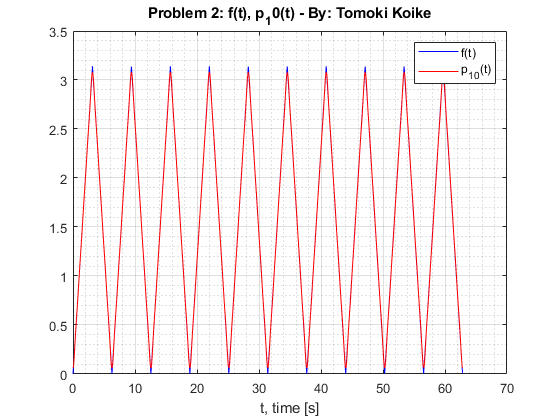

% Defining f(t)
T = 10*2*pi; % Generating 10 periods with fundamental frequency of 1Hz
fs = 100; % Sample frequency of 100Hz
t = 0:1/fs:T-1/fs; % Interval of time t
f = sawtooth(t,1/2); % Sawtooth function for f(t)
f = (f+1)*pi/2; % Manipulate the amplitude to get desired f(t)

% Defining p_10(t) Partial Fourier Series Approximation
p_10 = pi/2;
for kp = 1:2:10
    p_10 = p_10 - 4/pi/kp^2 * cos(kp.*t);
end

tp = linspace(0, T, length(t)); % Creating a vector for time, t

% Plotting 
figure(1)
plot(t, f, '-b')
xlabel('t, time [s]')
title('Problem 2: f(t), p_10(t) - By: Tomoki Koike')
grid on 
grid minor
box on
hold on
plot(tp, p_10, '-r')
hold off
legend('f(t)', 'p_1_0(t)')


% Calculating the error
a = [pi/2, -2/pi./(1:2:100000000-1).^2]; % Vectorizing a_k
e_10 = 2 * norm(a(11:length(a)))^2; 
% The error for || f(t) - p_10(t) || is going to be
disp(e_10);

   2.3023e-05



#### <PART 3>

Plot the power spectrum for $f$. Compute the root mean square of $f$, that is, compute the norm $||f||=\sqrt{\frac{1}{2\pi }\;\int_0^{2\pi } {|f\left(t\right)-p_n \left(t\right)|}^2 \mathrm{dt}\;}$

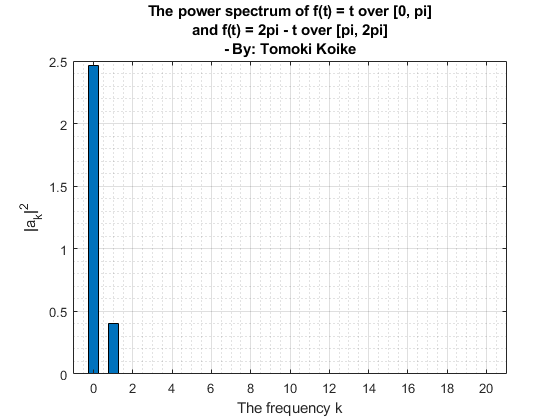

figure(2)
bar((0:20), abs(a(1:21).^2), 0.5)
grid on 
grid minor
box on
xlabel('The frequency k'); ylabel('|a_k|^2')
title({'The power spectrum of f(t) = t over [0, pi]',...
    'and f(t) = 2pi - t over [pi, 2pi]','- By: Tomoki Koike'})


% Calculating the root mean square
T = 2*pi; % Generating 10 periods with fundamental frequency of 1Hz
fs = 100; % Sample frequency of 100Hz
t = 0:1/fs:T-1/fs; % Interval of time t
f = sawtooth(t,1/2); % Sawtooth function for f(t)
f = (f+1)*pi/2; % Manipulate the amplitude to get desired f(t)
% The root mean square is 
rootMeanSqr = rms(f);
disp(rootMeanSqr);

    1.8143

